addpath("models/");
K = -eye(2);
load_system("bodysim.slx");
open("bodysim.slx");

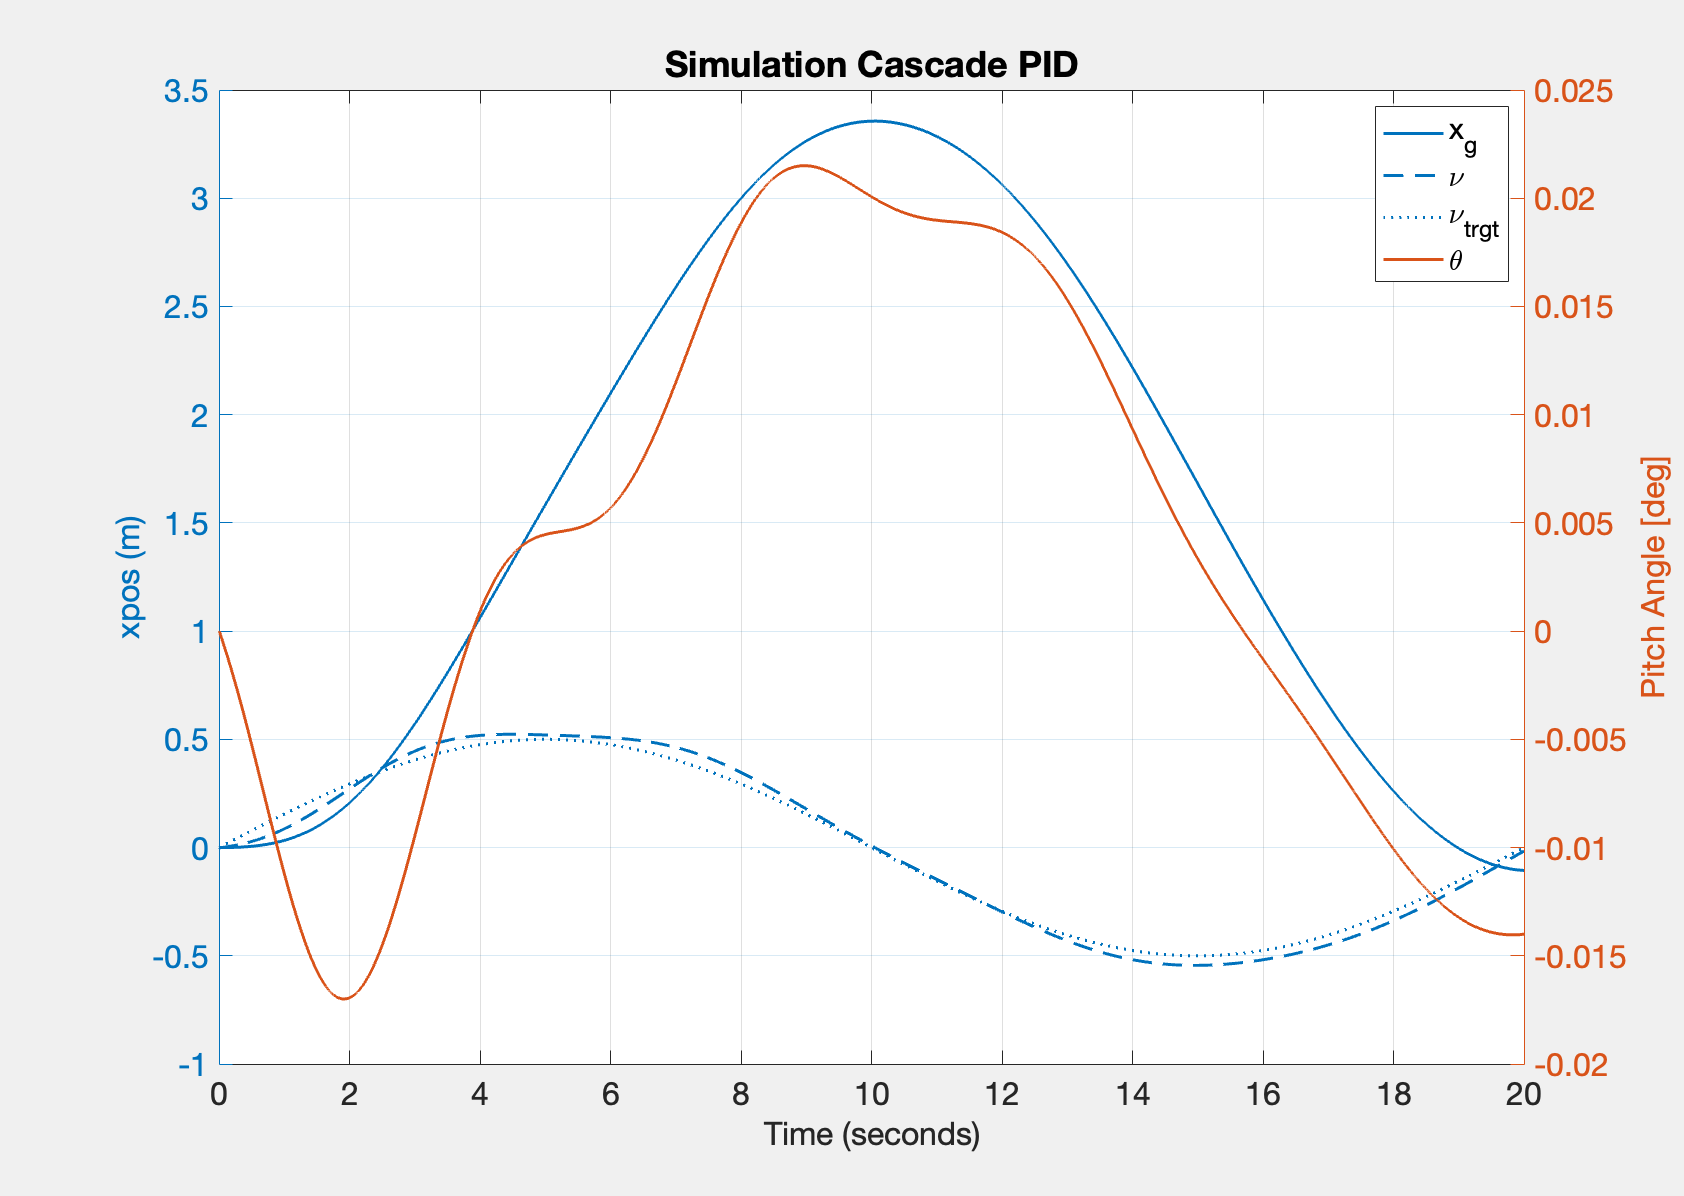

t = sim("bodysim.slx");
fig = figure;
yyaxis("left");
plot(t.xpos, 'linewidth', 1.5); hold on; 
plot(t.vel,'linewidth', 1.5); 
plot(t.vel_trgt, 'linewidth', 1.5);
yyaxis("right"); ylabel('Pitch Angle [deg]')
plot(t.theta,'linewidth', 1.5); hold off;
grid on;
fontsize(16, "points");
plotTitle = 'Simulation Cascade PID';
title(plotTitle, FontSize=18);
legend('x_g','\nu','\nu_{trgt}', '\theta' )

folderpath = fullfile("..", "Docs", "Y3Report", "Images", "Graphs", filesep);
filepath = fullfile(folderpath, plotTitle +".pdf");
set(fig, 'Units', 'inches', 'Position', [0 0 11.7 8.3]);
set(gcf,'Visible', 'on');
exportgraphics(fig, filepath)